Problem 1

Part 1

% spot rate
s_1 = 0.01;
s_2 = 0.015;
s_3 = 0.02;
s_4 = 0.025;
s_5 = 0.03;
s_6 = 0.035;
% forward rate
f_12 = (1+s_2)^2/(1+s_1)-1;
f_23 = (1+s_3)^3/(1+s_2)^2-1;
f_34 = (1+s_4)^4/(1+s_3)^3-1;
f_45 = (1+s_5)^5/(1+s_4)^4-1;
f_56 = (1+s_6)^6/(1+s_5)^5-1;
f_12 = round(f_12,4);
f_12

f_12 =                       0.02


f_23 = round(f_23,4);
f_23

f_23 =                     0.0301


f_34 = round(f_34,4);
f_34

f_34 =                     0.0401


f_45 = round(f_45,4);
f_45

f_45 =                     0.0502


f_56 = round(f_56,4);
f_56

f_56 =                     0.0604


% input arguments
c = [108,94,99,92.7,96.6,95.9,92.9,110,...
    104,101,107,102,95.2,0,0,0,0,0]';
A = -[10,7,8,6,7,6,5,10,8,6,10,7,100,-1,0,0,0,0;
      10,7,8,6,7,6,5,10,8,6,110,107,0,1+f_12,-1,0,0,0;
      10,7,8,6,7,6,5,110,108,106,0,0,0,0,1+f_23,-1,0,0;
      10,7,8,6,7,106,105,0,0,0,0,0,0,0,0,1+f_34,-1,0;
      10,7,8,106,107,0,0,0,0,0,0,0,0,0,0,0,1+f_45,-1;
      110,107,108,0,0,0,0,0,0,0,0,0,0,0,0,0,0,1+f_56];
b= -[500,200,800,400,700,900];
Aeq=[];
beq =[];
lb =[0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0];
ub = [inf;inf;inf;inf;inf;inf;inf;inf;...
    inf;inf;inf;inf;inf;inf;inf;inf;inf;inf];
% linprog output
[x_part1, fval_part1] = linprog(c,A,b,Aeq,beq,lb,ub);

Optimal solution found.



% optimal solution
x_part1 = round(x_part1,4);
x_part1

x_part1 =                     8.1818
                         0
                         0
                         0
                    5.7774
                    2.6202
                         0
                         0
                    6.1298
                         0


% objective function value
fval_part1 = round(fval_part1,6);
fval_part1

fval_part1 =                2639.969419


Part 2

% input arguments
c = [108,94,99,92.7,96.6,95.9,92.9,110,...
    104,101,107,102,95.2,0,0,0,0,0]';
A = -[10,7,8,6,7,6,5,10,8,6,10,7,100,-1,0,0,0,0;
      10,7,8,6,7,6,5,10,8,6,110,107,0,1+f_12,-1,0,0,0;
      10,7,8,6,7,6,5,110,108,106,0,0,0,0,1+f_23,-1,0,0;
      10,7,8,6,7,106,105,0,0,0,0,0,0,0,0,1+f_34,-1,0;
      10,7,8,106,107,0,0,0,0,0,0,0,0,0,0,0,1+f_45,-1;
      110,107,108,0,0,0,0,0,0,0,0,0,0,0,0,0,0,1+f_56;
      -108*0.5,-94*0.5,-99*0.5,-92.7*0.5,-96.6*0.5,...
      -95.9*0.5,92.9*0.5,110*0.5,104*0.5,101*0.5,...
      107*0.5,102*0.5,95.2*0.5,0,0,0,0,0];
b= -[500,200,800,400,700,900,0];
Aeq=[];
beq =[];
lb =[0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0];
ub = [inf;inf;inf;inf;inf;inf;inf;inf;...
    inf;inf;inf;inf;inf;inf;inf;inf;inf;inf];
% linprog output
[x_part2, fval_part2] = linprog(c,A,b,Aeq,beq,lb,ub);

Optimal solution found.



% optimal solution
x_part2 = round(x_part2,4);
x_part2

x_part2 =                          0
                    8.4112
                         0
                         0
                    5.5027
                         0
                    3.3565
                         0
                    6.3502
                         0


% objective function value
fval_part2 = round(fval_part2,6);
fval_part2

fval_part2 =                2644.424804


Part 3

% input arguments
c = [108,94,99,92.7,96.6,95.9,92.9,110,...
    104,101,107,102,95.2,0,0,0,0,0]';
A = -[10,7,8,6,7,6,5,10,8,6,10,7,100,-1,0,0,0,0;
      10,7,8,6,7,6,5,10,8,6,110,107,0,1+f_12,-1,0,0,0;
      10,7,8,6,7,6,5,110,108,106,0,0,0,0,1+f_23,-1,0,0;
      10,7,8,6,7,106,105,0,0,0,0,0,0,0,0,1+f_34,-1,0;
      10,7,8,106,107,0,0,0,0,0,0,0,0,0,0,0,1+f_45,-1;
      110,107,108,0,0,0,0,0,0,0,0,0,0,0,0,0,0,1+f_56;
      -0.75*108,-0.75*94,-0.75*99,-0.75*92.7,...
      -0.75*96.6,-0.75*95.9,0.25*92.9,0.25*110,...
      0.25*104,0.25*101,0.25*107,0.25*102,0.25*95.2,0,0,0,0,0];
b= -[500,200,800,400,700,900,0];
Aeq=[];
beq =[];
lb =[0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0];
ub = [inf;inf;inf;inf;inf;inf;inf;inf;inf;...
    inf;inf;inf;inf;inf;inf;inf;inf;inf];
% linprog output
[x_part3, fval_part3] = linprog(c,A,b,Aeq,beq,lb,ub);

Optimal solution found.



% optimal solution
x_part3 = round(x_part3,4);
x_part3

x_part3 =                          0
                    7.1267
                         0
                         0
                         0
                         0
                   10.4054
                         0
                    6.4638
                         0


% objective function value
fval_part3 = round(fval_part3,6);
fval_part3

fval_part3 =                2679.651552


Problem 2

Part 1

b)

format long g
n=3;
% expected returns of assets 
mu=[0.01127,0.00184,0.00370]; 
% covariance matrix
Q=[.00168,-.00011,.00101;
   -.00011,.00013,-.00003;
   .00101,-.00003,.00132];
% expected return goals range from 0.2% to 1.2% 
goal_R=(0.2:.1:1.2)/100;
c=zeros(n,1);
x=zeros(11,3);
fval=zeros(11,1);
std_devi=zeros(11,1);
Aeq=[ones(1,n)]; 
beq=1;
for a=1:length(goal_R)
    A=-mu; 
    b=-goal_R(a); 
    [x(a,:), fval(a,1)] = quadprog(Q, c, A,b, Aeq,beq,[],[]); 
    % standard deviation = (x'*Q*x)^.5
    std_devi(a,1)=(x(a,:)*Q*x(a,:)')^.5; 
    x = round(x,4);
    fval = round(fval,8);
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

% optimal solution
x

x =                     0.1105                    0.8772                    0.0123
                    0.1228                    0.8735                    0.0037
                    0.2452                    0.8367                   -0.0819
                    0.3682                    0.7997                    -0.168
                    0.4913                    0.7628                    -0.254
                    0.6143                    0.7258                   -0.3401
                    0.7373                    0.6888                   -0.4261
                    0.8603                    0.6519                   -0.5122
                    0.9833                    0.6149                   -0.5982
                    1.1063                    0.5779                   -0.6842


% variance
var = fval*2;
var

var =                 0.00010152
                0.00010166
                0.00011928
                0.00016652
                0.00024336
                 0.0003498
                0.00048586
                 0.0006515
                0.00084676
                0.00107162


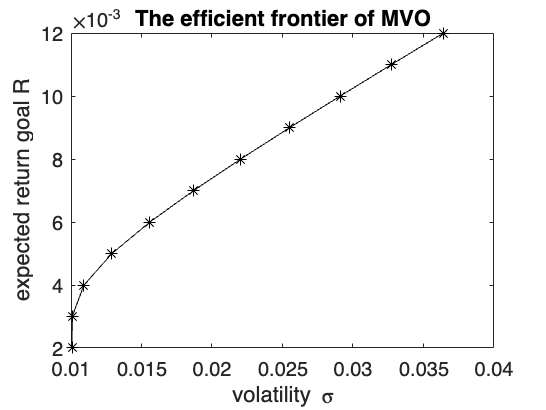

% plot efficient frontier
plot(std_devi, goal_R, '-k*') 
xlabel('volatility \sigma') 
ylabel('expected return goal R') 
title('The efficient frontier of MVO')

Part 2

b)

n=8;
% expected returns of assets 
mu=[0.01127,0.00184,0.00370,0.01502,...
    0.01709,0.00930,0.01267,0.01716]; 
% covariance matrix
Q=[0.00168,-0.00011,0.00101,0.00084,...
    0.00151,0.00095,0.00130,0.00187;
   -0.00011,0.00013,-0.00003,-0.00010,...
   0.00003,-0.00001,-0.00008,-0.00007;
   0.00101,-0.00003,0.00132,0.00022,...
   0.00082,0.00033,0.00036,0.00082;
   0.00084,-0.00010,0.00022,0.00304,...
   0.00108,0.00195,0.00186,0.00103;
   0.00151,0.00003,0.00082,0.00108,...
   0.00352,0.00105,0.00143,0.00220;
   0.00095,-0.00001,0.00033,0.00195,...
   0.00105,0.00425,0.00167,0.00127;
   0.00130,-0.00008,0.00036,0.00186,...
   0.00143,0.00167,0.00312,0.00183;
   0.00187,-0.00007,0.00082,0.00103,...
   0.00220,0.00127,0.00183,0.00359];
% expected return goals range from 0.2% to 2.0% 
goal_R=(0.2:0.2:2.0)/100;
c=zeros(n,1);
x=zeros(10,8);
fval=zeros(10,1);
std_devi=zeros(10,1);
Aeq=[ones(1,n)]; 
beq=1;
for a=1:length(goal_R)
    A=-mu; 
    b=-goal_R(a); 
    [x(a,:), fval(a,1)] = quadprog(Q, c, A,b, Aeq,beq,[],[]); 
    % standard deviation = (x'*Q*x)^.5
    std_devi(a,1) = (x(a,:)*Q*x(a,:)')^.5; 
    x = round(x,4);
    fval = round(fval,8);
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

% optimal solution
x

x =                     0.1603                    0.8723                    0.0049                    0.0507                   -0.0485                   -0.0169                   -0.0034                   -0.0194
                    0.1929                    0.8298                   -0.0425                    0.0866                   -0.0224                   -0.0274                   -0.0189                    0.0019
                    0.2485                    0.7572                   -0.1234                     0.148                    0.0223                   -0.0454                   -0.0454                    0.0383
                    0.3041                    0.6845                   -0.2043                    0.2094                    0.0669                   -0.0634                   -0.0719                    0.0747
                    0.3597                    0.6119                   -0.2852                    0.2707                    0.1116                   -0.0814    

% variance
var = fval*2;
var

var =                   9.09e-05
                 0.0001035
                0.00018332
                 0.0003367
                0.00056358
                0.00086402
                0.00123798
                0.00168548
                0.00220652
                0.00280108


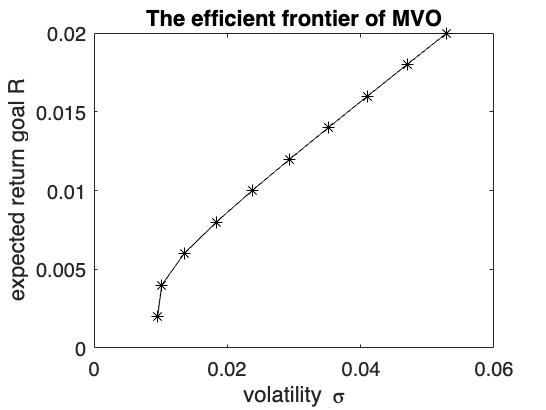

% plot efficient frontier
plot(std_devi, goal_R, '-k*') 
xlabel('volatility \sigma') 
ylabel('expected return goal R') 
title('The efficient frontier of MVO')